T_beta = sym([.5 .5 .25; .25 0 .25; .25 .5 .5])

$$T\_beta = \left(\begin{array}{ccc} \frac{1}{2} & \frac{1}{2} & \frac{1}{4}\\ \frac{1}{4} & 0 & \frac{1}{4}\\ \frac{1}{4} & \frac{1}{2} & \frac{1}{2} \end{array}\right)$$

% T_beta2 = sym([.4375, .375, .375; .1875, .25, .1875; .375, .375, .4375])
% T_beta^2
vpa(T_beta^2)

$$ans = \left(\begin{array}{ccc} 0.4375 & 0.375 & 0.375\\ 0.1875 & 0.25 & 0.1875\\ 0.375 & 0.375 & 0.4375 \end{array}\right)$$

[w, l] = eig(T_beta)

$$w = \left(\begin{array}{ccc} 1 & -1 & 1\\ \frac{1}{2} & 0 & -2\\ 1 & 1 & 1 \end{array}\right)$$

$$l = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \frac{1}{4} & 0\\ 0 & 0 & -\frac{1}{4} \end{array}\right)$$


v = sym([2/5; 1/5; 2/5])

$$v = \left(\begin{array}{c} \frac{2}{5}\\ \frac{1}{5}\\ \frac{2}{5} \end{array}\right)$$

T_beta*v

$$ans = \left(\begin{array}{c} \frac{2}{5}\\ \frac{1}{5}\\ \frac{2}{5} \end{array}\right)$$

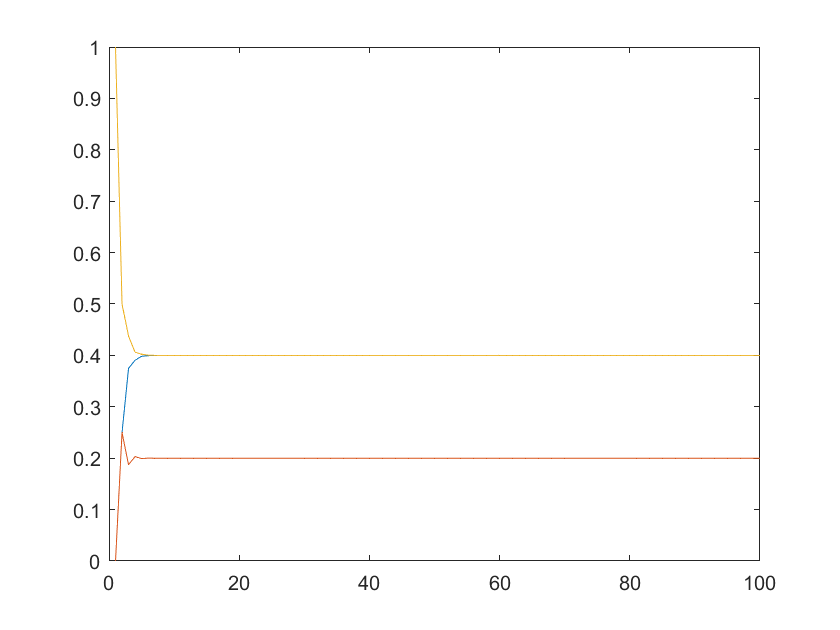



%[r,n,c]
ndays = 100;
weather = zeros(3,ndays);
%wNew = [1;0;0];
%wNew = [0;1;0];
wNew = [0;0;1];
for i = 1:ndays
    wOld = wNew;
    weather(:,i) = wOld;
    wNew = T_beta*wOld;
end

plot([1:ndays],weather(1,:)); hold on;
plot([1:ndays],weather(2,:)); hold on;
plot([1:ndays],weather(3,:))